# Robust Maneuver Planning for Autonomous Vehicles

# Frenet Coordinates

# Model Initialisation

The [VehicleFollowingInit](matlab:open('./VehicleFollowingInit.m')) script was created to specify and vary parameters for the simulation and to initialize the Simulink model. The script will be executed automatically when opening the [VehicleFollowing](matlab:open_system('VehicleFollowing.slx')) model.

## Space Discretisation

Also during initialisation, the continiuous road trajectory will be divided into discrete cells ([discretiseContinuousSpace](matlab:matlab.desktop.editor.openAndGoToLine(which('VehicleFollowingInit.m'),  getFunctionLineNr('discretiseContinuousSpace'));)):

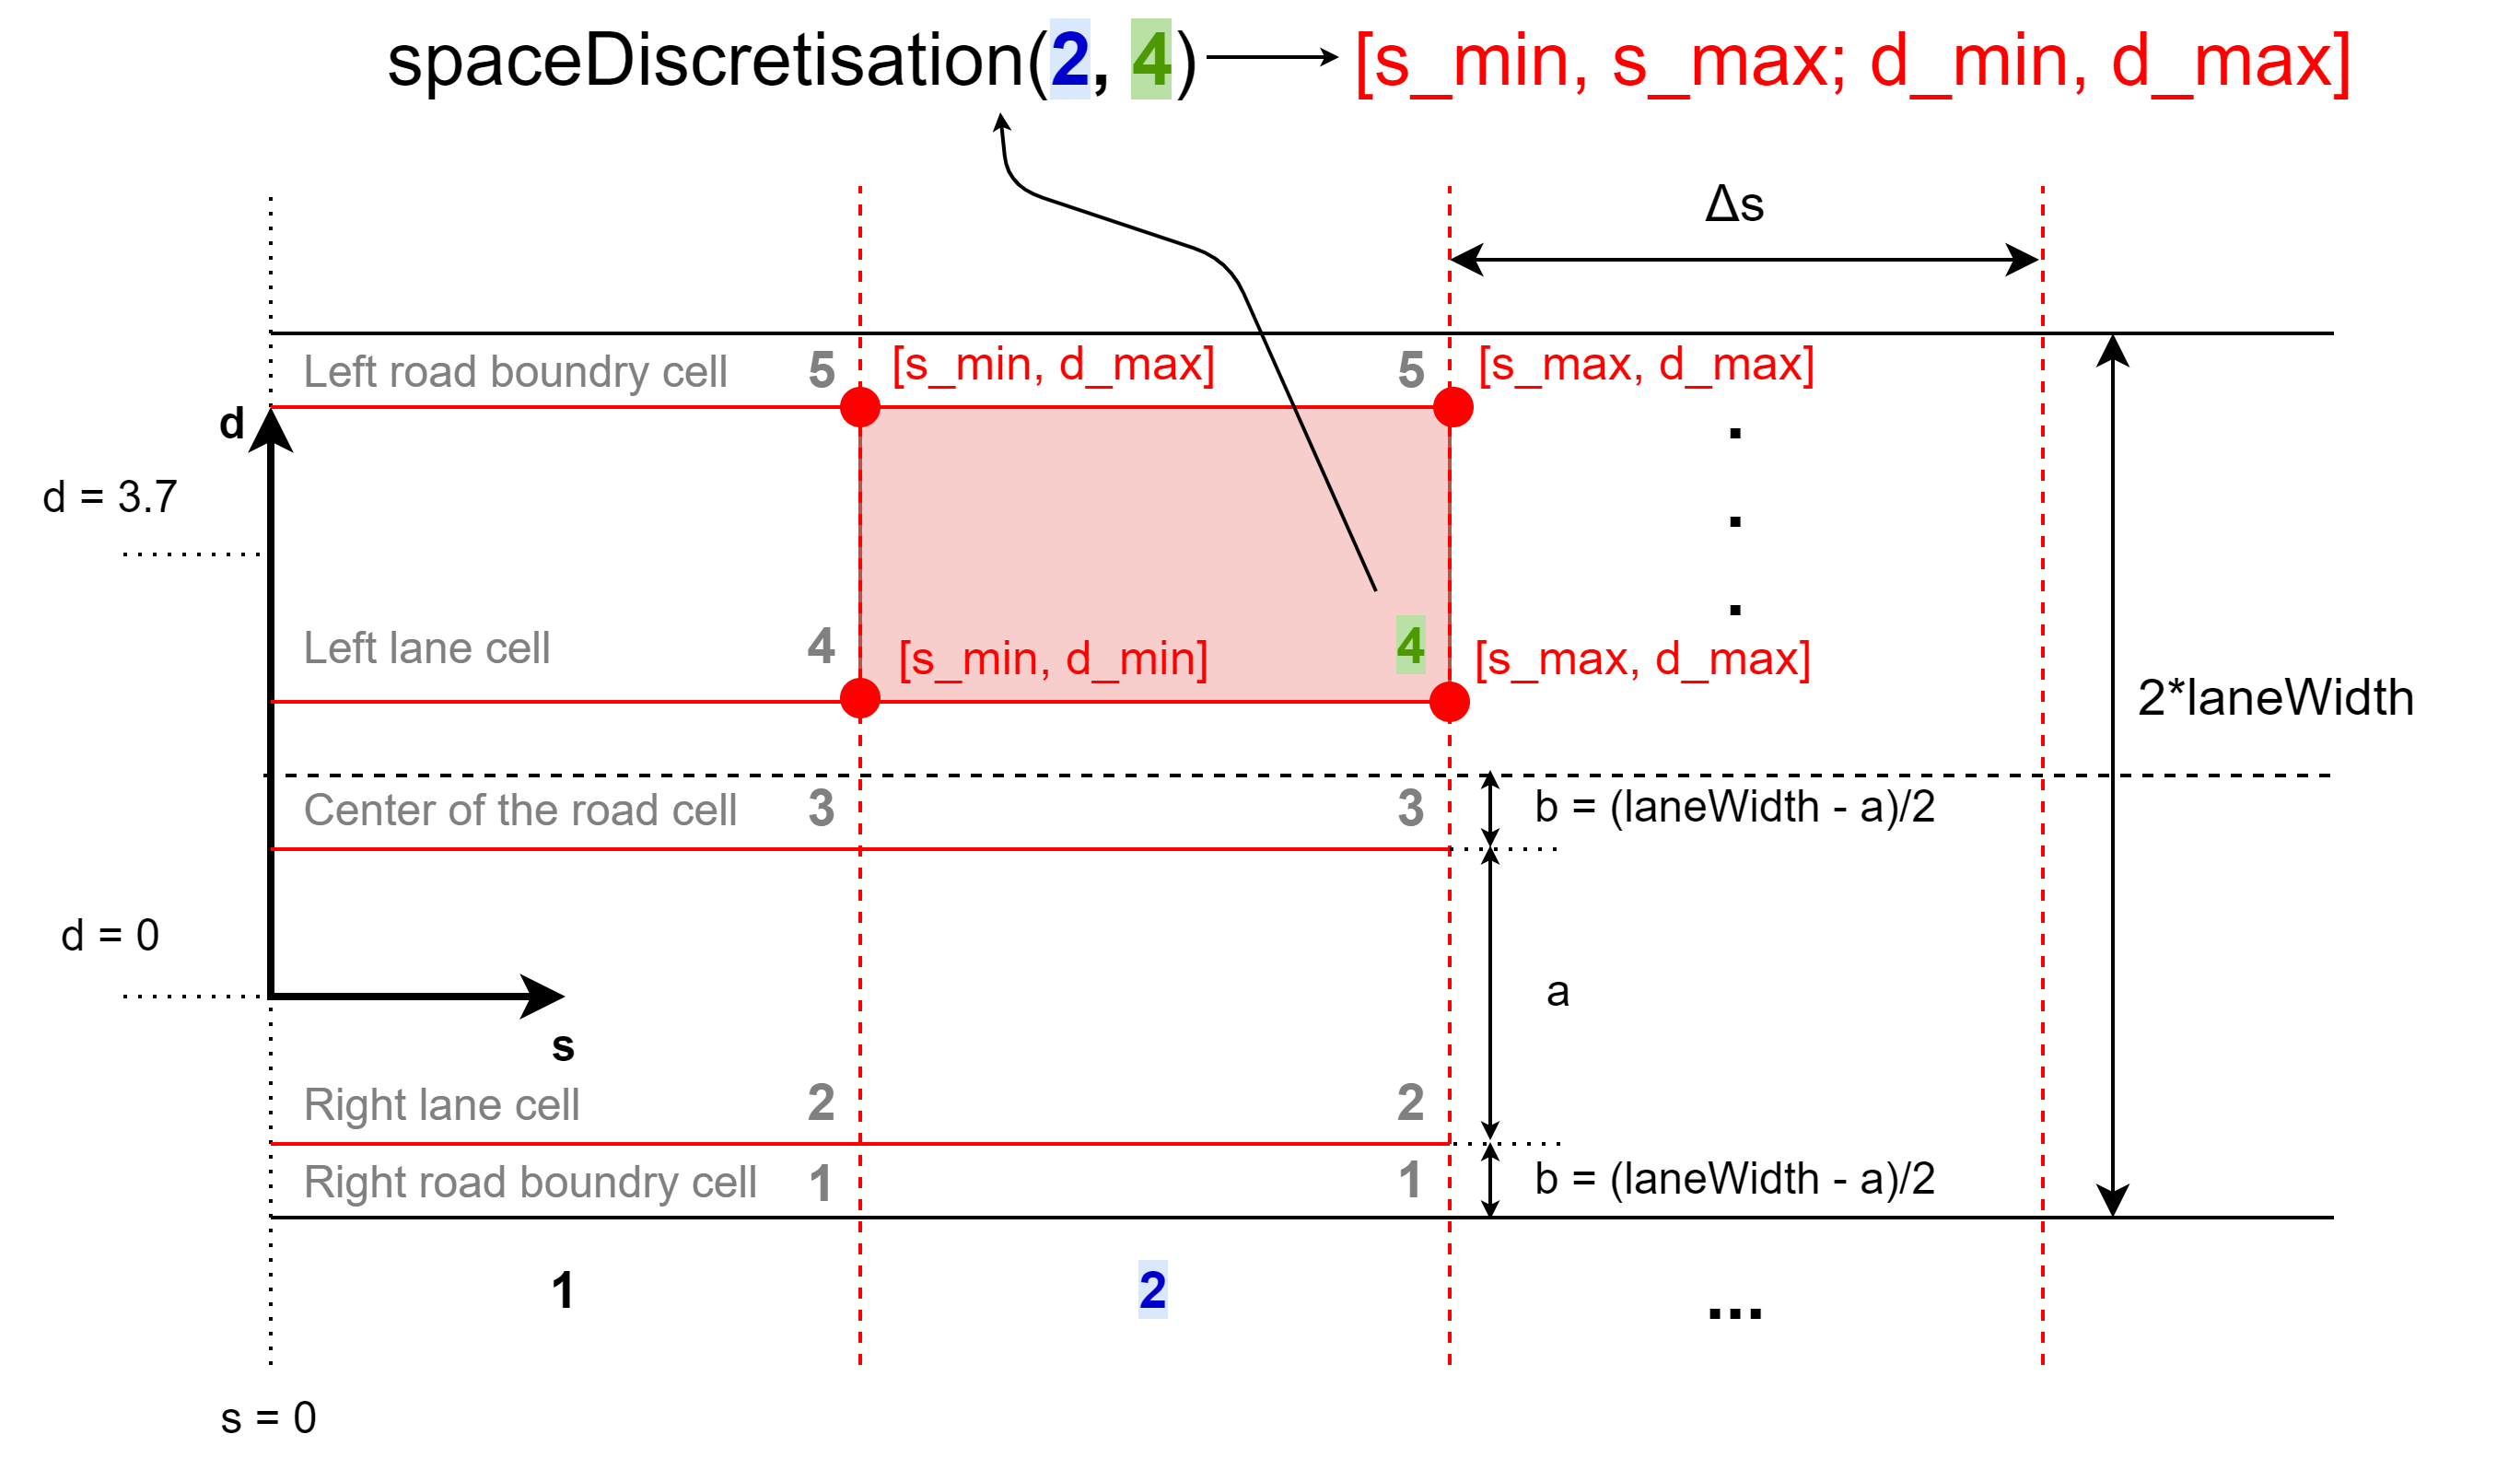

 As the figure shows, the road's length ($s$-coordinate) is divided into equal sized parts $\Delta s$. The road's width is divided into different sized parts. So for each $\Delta s$, 5 discrete cells are created:

- Right road boundry cell (1)

- Right lane cell (2)

- Center of the road cell (3)

- Left lane cell (4)

- Left road boundry cell (5)

For this, a cell_length $\Delta s$ and a laneCell_width $a$ must be specified. The width $b$ to set the width of the road boundry cells and the center of the road cell is defined as:

 
$$b = \frac{laneWidth-a}{2}$$


This follows from:


$$a + 2b = laneWidth$$


The continuous cell boundries **[s_min, s_max; d_min, d_max]** are stored in the cell array structure (they are seperately stored in the matrix structure *spaceDiscretisationMatrix *to reduce computational resources when working with the structure) *spaceDiscretisation*:

VehicleFollowingInit;
spaceDiscretisation

spaceDiscretisation = 315×5 cell array
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}
    {2×2 double}    {2×2 double}    {2×2 double}    {2×2 double}    {2

Because Frenet coordinates are used, the discretisation also easily works for curved roads.

### Discrete to Continuous

To get the continuous boundries **[s_min, s_max; d_min, d_max] **of a discrete cell, the function [Discrete2Continuous](matlab:open('./Vehicle Functions\Helper Functions\Discrete2Continuous.m')) can be used.

### Continuous to Discrete

To get the index of a discrete cell for a given continuous $s$ and $d$ value, the function [Continuous2Discrete](matlab:open('./Vehicle Functions\Helper Functions\Continuous2Discrete.m')) can be used.

# Kinematic Bicycle Model

The kinematic bicycle model can be used to simulate simplified car-like vehicle dynamics. The coordinate origin of this model is defined at the center of the bicycle's rear axle, which defines the body coordinate system $x_{b}$ and $y_{b}$. For the Simulink block, the used inputs that are the vehicle's velocity $v$ in $\frac{m}{s}$ and the steering angle $\psi$ in rad. The model outputs the state **[x, y, θ] **of the model, which is the vehicle's pose.

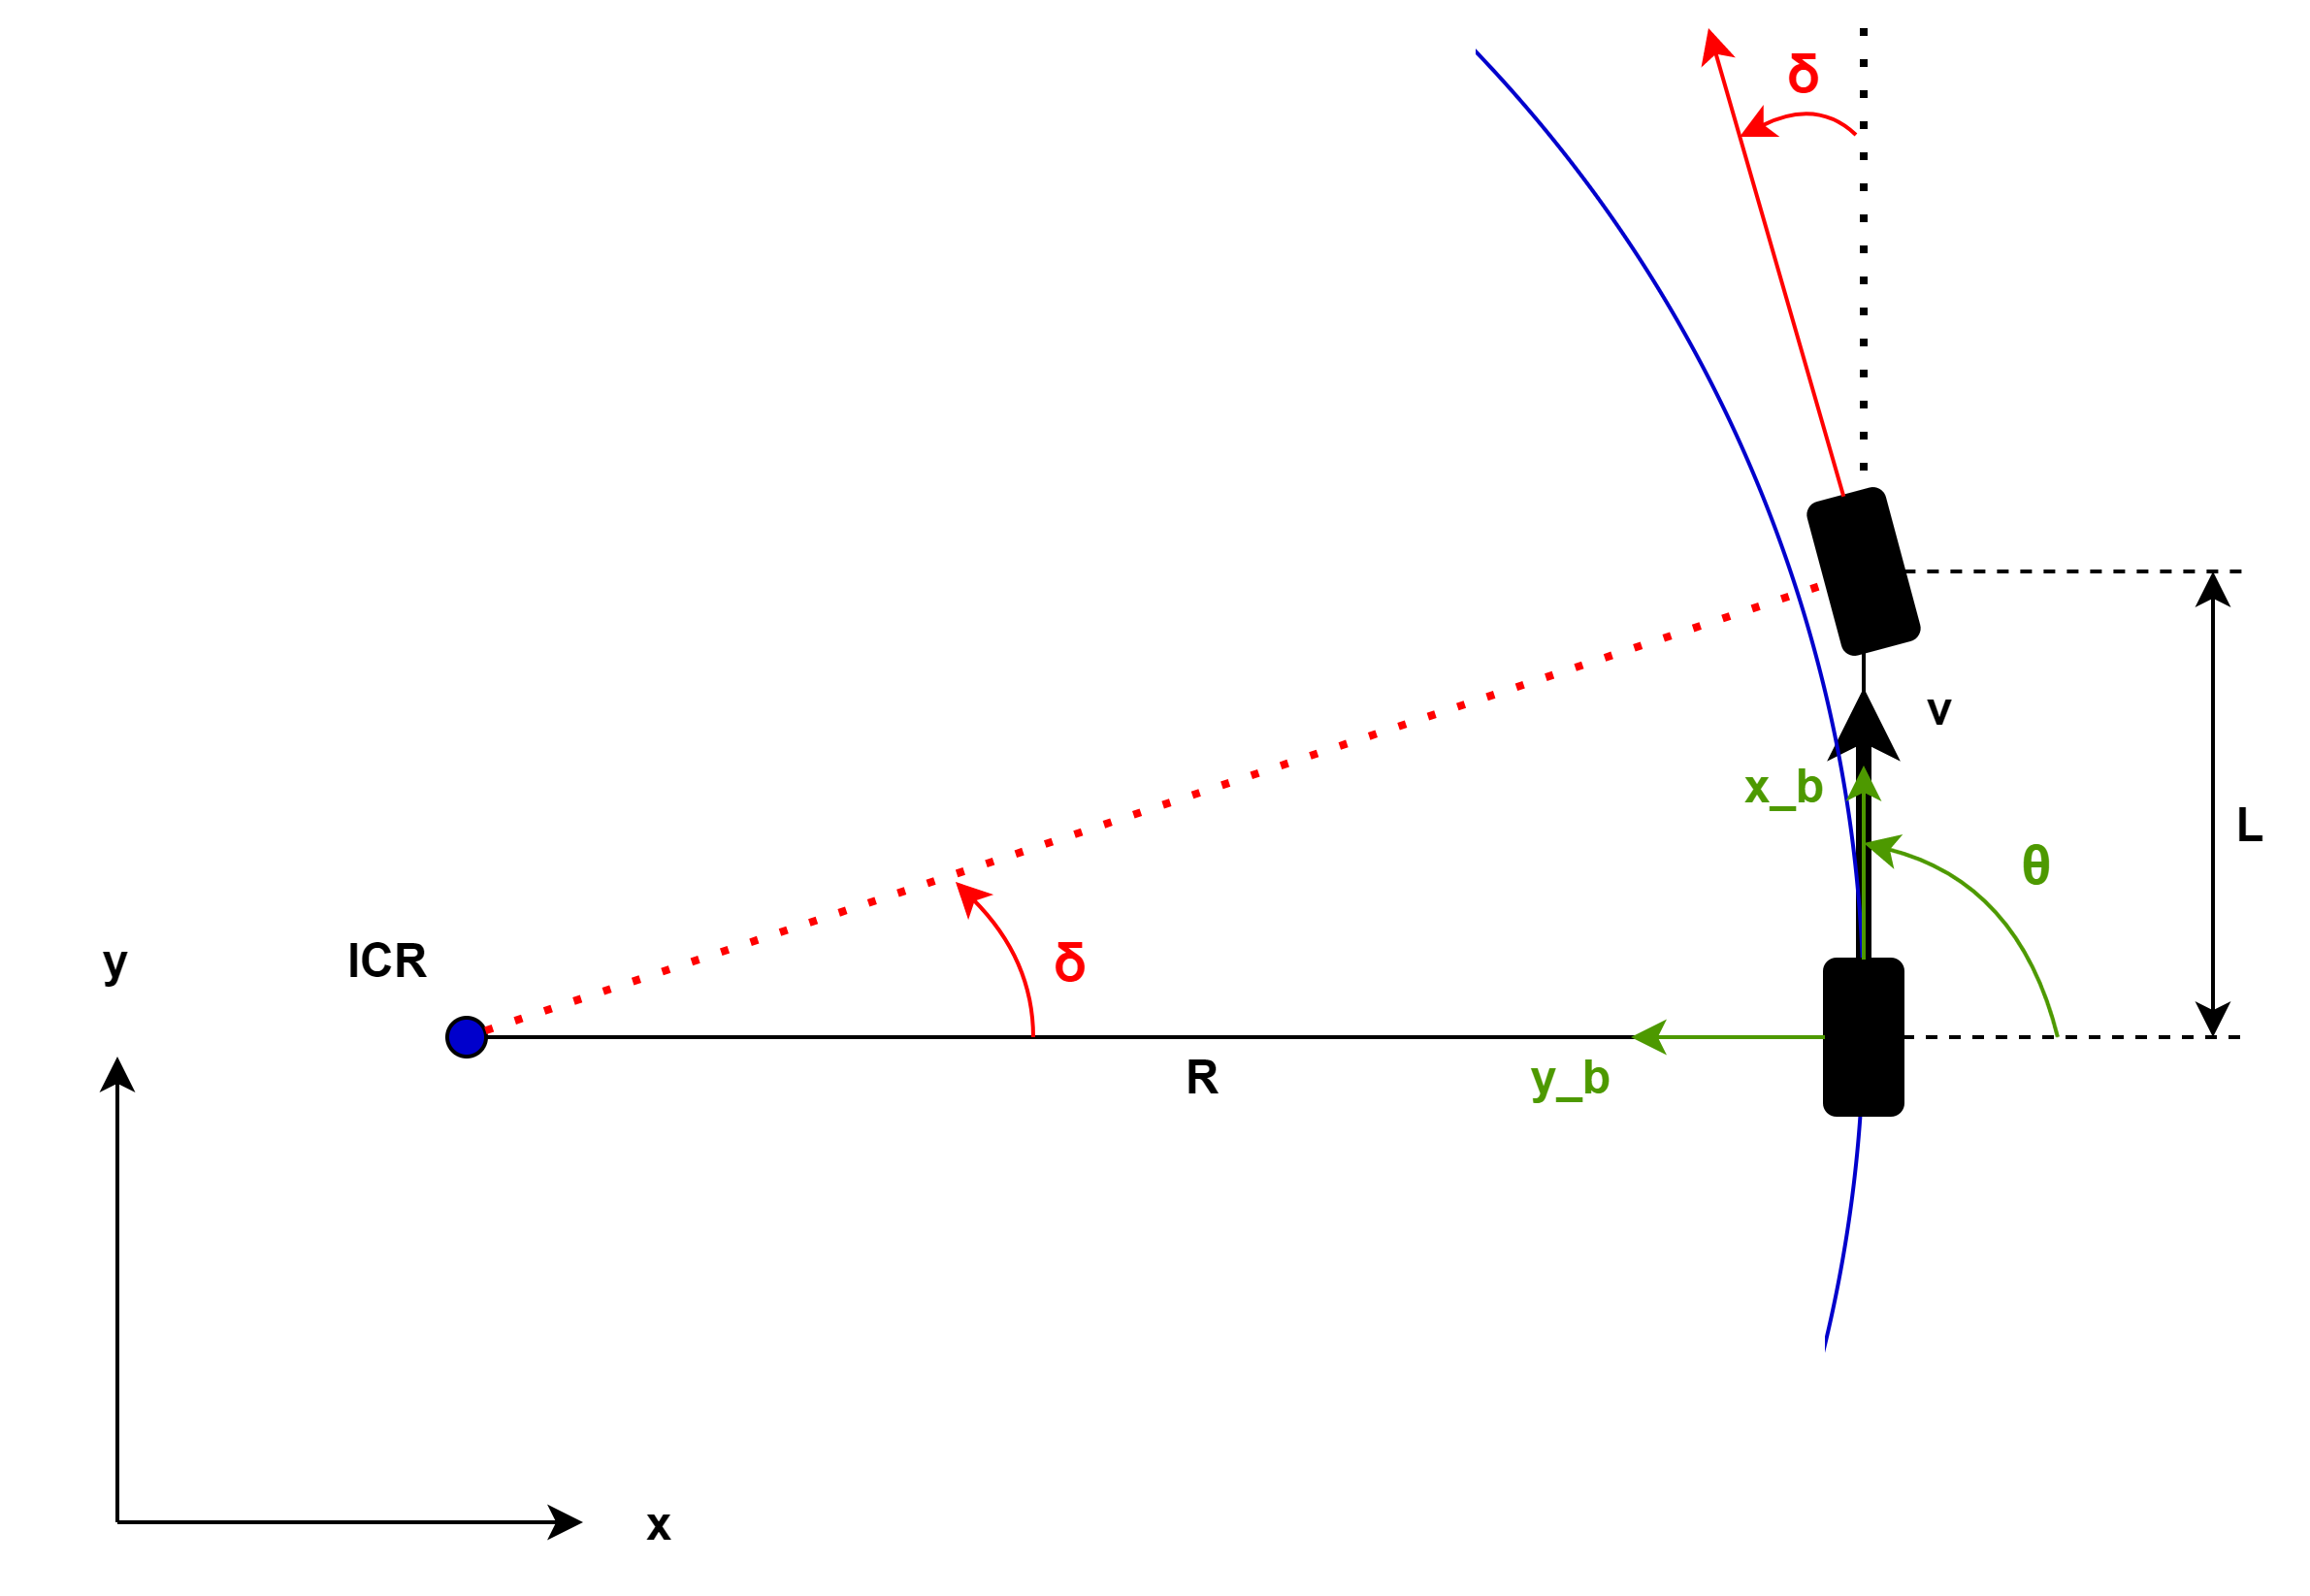

### Equations of motion

The origin of the body coordinate system moves along a circular path. The circle's center is the Instantaneous Center of Rotation (ICR) and has the radius $R$. Thus the eqations of motion are: 


$$\dot x = v \cos(\theta) \\
\dot y = v \sin(\theta) \\ 
\dot \theta = \frac{v}{L}tan(\gamma)$$


The maximum steering angle $\delta_{max}$  and the wheel base $L$ limit the radius $R$ or respectively the curvature $\kappa$:


$$R_{min} = \frac{L}{tan(\delta_{max})} \\
\kappa_{max} = \frac{1}{R_{min}}  = \frac{tan(\delta_{max})}{L} \\ 
$$


### References

[https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html](https://www.mathworks.com/help/robotics/ref/bicyclekinematicmodel.html)

Corke, Peter I. *Robotics, Vision and Control: Fundamental Algorithms in MATLAB*. Springer, 2011.

# Coordinate Transformations

# Vehicles

# Decision Unit

# Longitudinal Control

# Lateral Motion Control

In this Model one of two lateral controllers can be chosen. Using a Simulink Variant Subsystem block, either Pure Pursuit controller or Stanley controller can be selected. For Pure Pursuit, reference waypoints on the desired path need to be generated. The lateral Stanley controller on the other hand needs a reference pose on the path according to its front axle at every time step. Therefore the MATLAB Systems [PurePursuitWPGenerator.m](matlab:open('./Vehicle Functions\PurePursuitWPGenerator.m')) and [StanleyPoseGenerator.m](matlab:open('./Vehicle Functions\StanleyPoseGenerator.m')) were created. Both of them are a subclass of the [LocalTrajectoryPlanner.m](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner.m')).

## Local Trajectory Planner

### Generate Reference Trajectory

The purpose of the [LocalTrajectoryPlanner.m](matlab:open('./Vehicle Functions\LocalTrajectoryPlanner.m')) is to generate a reference trajectory for the ego vehicle to either follow the lane or to execute a lane changing maneuver. Also functions to operate with the generated trajectory which are necessary for both Pure Pursuit and Lateral Stanley Control are provided.

The trajectory will be planned in the Frenet coordinate system for a previously defined time horizon ([planFrenetTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('planFrenetTrajectory'));)):

The planned Frenet trajectory contains the waypoints for the future time horizon. The waypoints have the following format:

Normally, if there is no lane changing command, this function will just plan the reference trajecory to be on the right lane for the predefined time horizon ([calculateStraightTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateStraightTrajectory'));)). Therefore a prediction of the final $s$ value after this time will be made according to the ego velocity. The $d$ value will stay constant for this trajectory. At every time step, passed waypoints will be removed from the reference trajectory and new ones will be added, so that the length of the trajectory is always correct according to the time horizon and the sample time ([updateCurrentTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('updateCurrentTrajectory'));)): 

If there is a command to change lane, the previously planned trajectory will be discarded and instead the lane changing trajectory will be used. To generate the lane changing trajectory, the minimum jerk trajectory either to the left or right lane for a previously defined maneuver time will be calculated ([calculateLaneChangingTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateLaneChangingTrajectory'));)). The lane calculated lane changing trajectory might be shorter or longer than the time horizon. To fit the reference length for the trajectory to plan, either a straight trajectory ([calculateStraightTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateStraightTrajectory'));)) must be added if the maneuver time is shorter than the time horizon, or a resiudal lane changing trajectory must be kept and added to the planned trajectory later in case it is longer ([divideLaneChangingTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('divideLaneChangingTrajectory'));)) ([calculateTrajectoryToAdd](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateTrajectoryToAdd'));)).

### Operate with Reference Trajectory

The generated reference trajectory can be transformed from Frenet to Cartesian coordinate system ([getCurrentTrajectoryCartesian](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getCurrentTrajectoryCartesian'));)). The waypoints have the following format:

Furthermore, according to the current $s$ value, a number of next waypoints in the planned Frenet trajectory can be returned ([getNextFrenetTrajectoryWaypoints](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getNextFrenetTrajectoryWaypoints'));)).

The error between the predicted $s$ and $d$ value of the planned trajectory and the actual values after the time according to the predifined time horizon has passed, can be tracked ([calculateTrajectoryError](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('calculateTrajectoryError'));)). The error will be computed every few seconds. This period of time will be a specified fraction of the time horizon. If the error exceeds a certain value, this function can be used to generate a command for replanning the trajectory.

## Pure Pursuit Controller

Pure Pursuit is an algorithm that is used for path tracking. It takes the vehicle's current pose **[x, y, θ] **and the next waypoints' coordinates **[x, y]** as an input. The figure shows the desired path defined by different waypoints (WPs) and the vehicle's current position and orientation. 

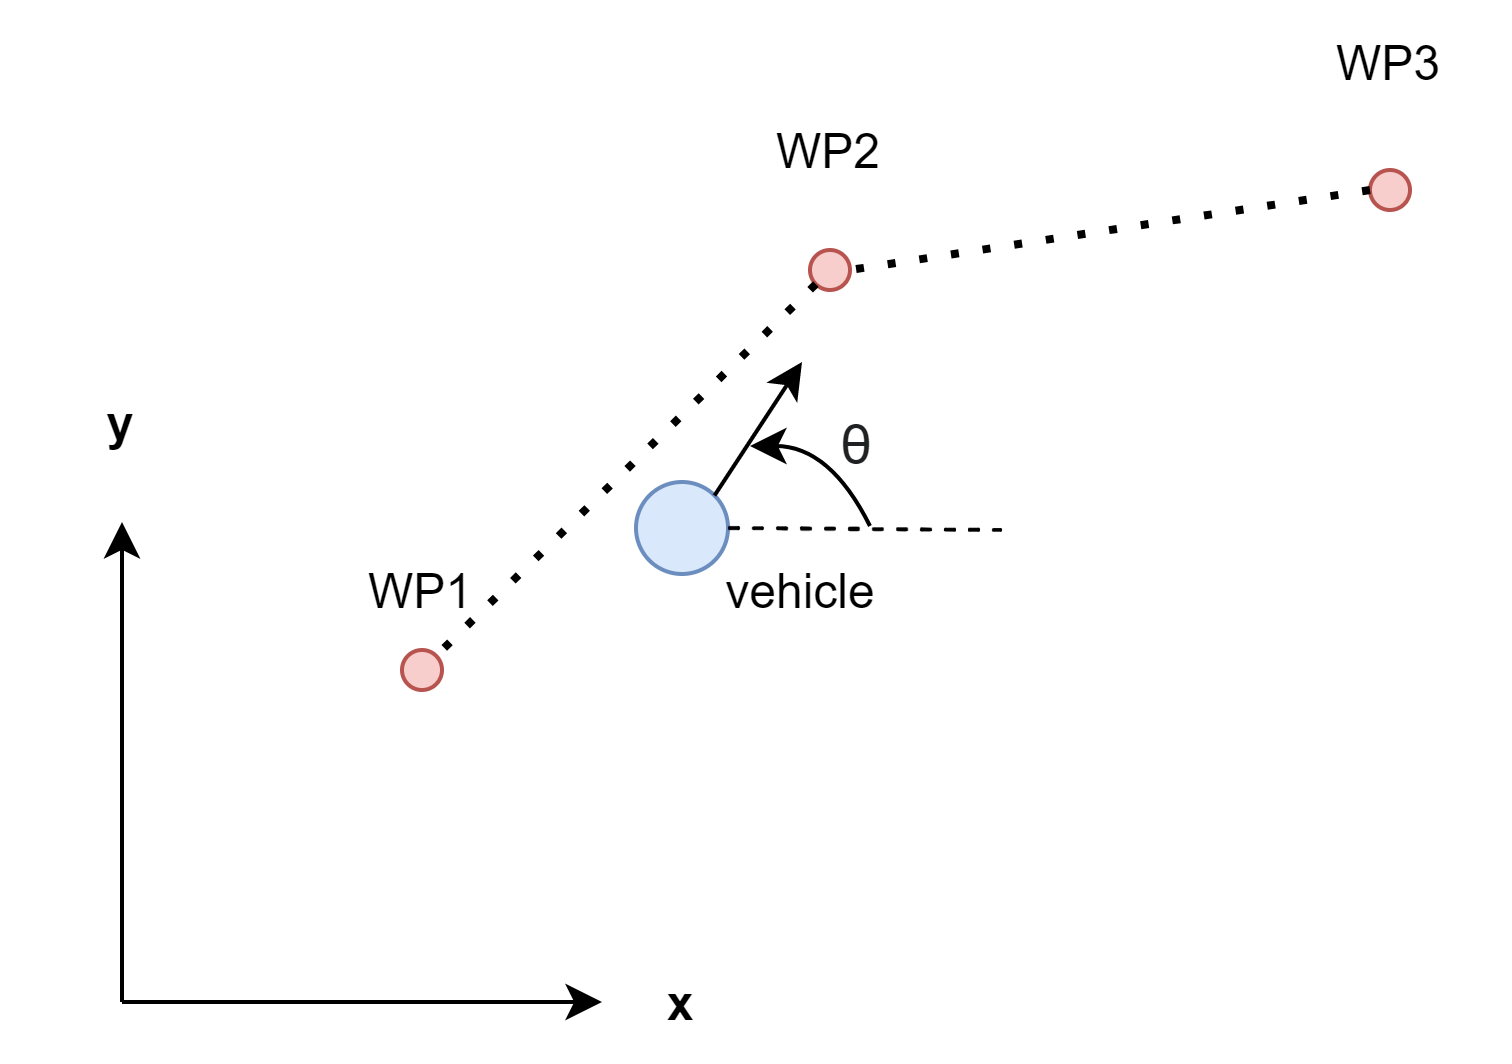

### Look Ahead Distance

To tune this algorithm, the look ahead distance $l_d$ can be adjusted. It states how far ahead on the path the vehicle should look from its current position. A small look ahead distance results in quickly moving towards the path but thus overshoots are possible. A large look ahead distance on the other hand avoids these overshoots but lets the vehicle move slower towards the path which may result in larger curvatures in corners.

### Steering Angle

The output that is used to compute the steering angle $\delta$ command for the vehicle kinematic bicycle model, is the target direction $\alpha$:

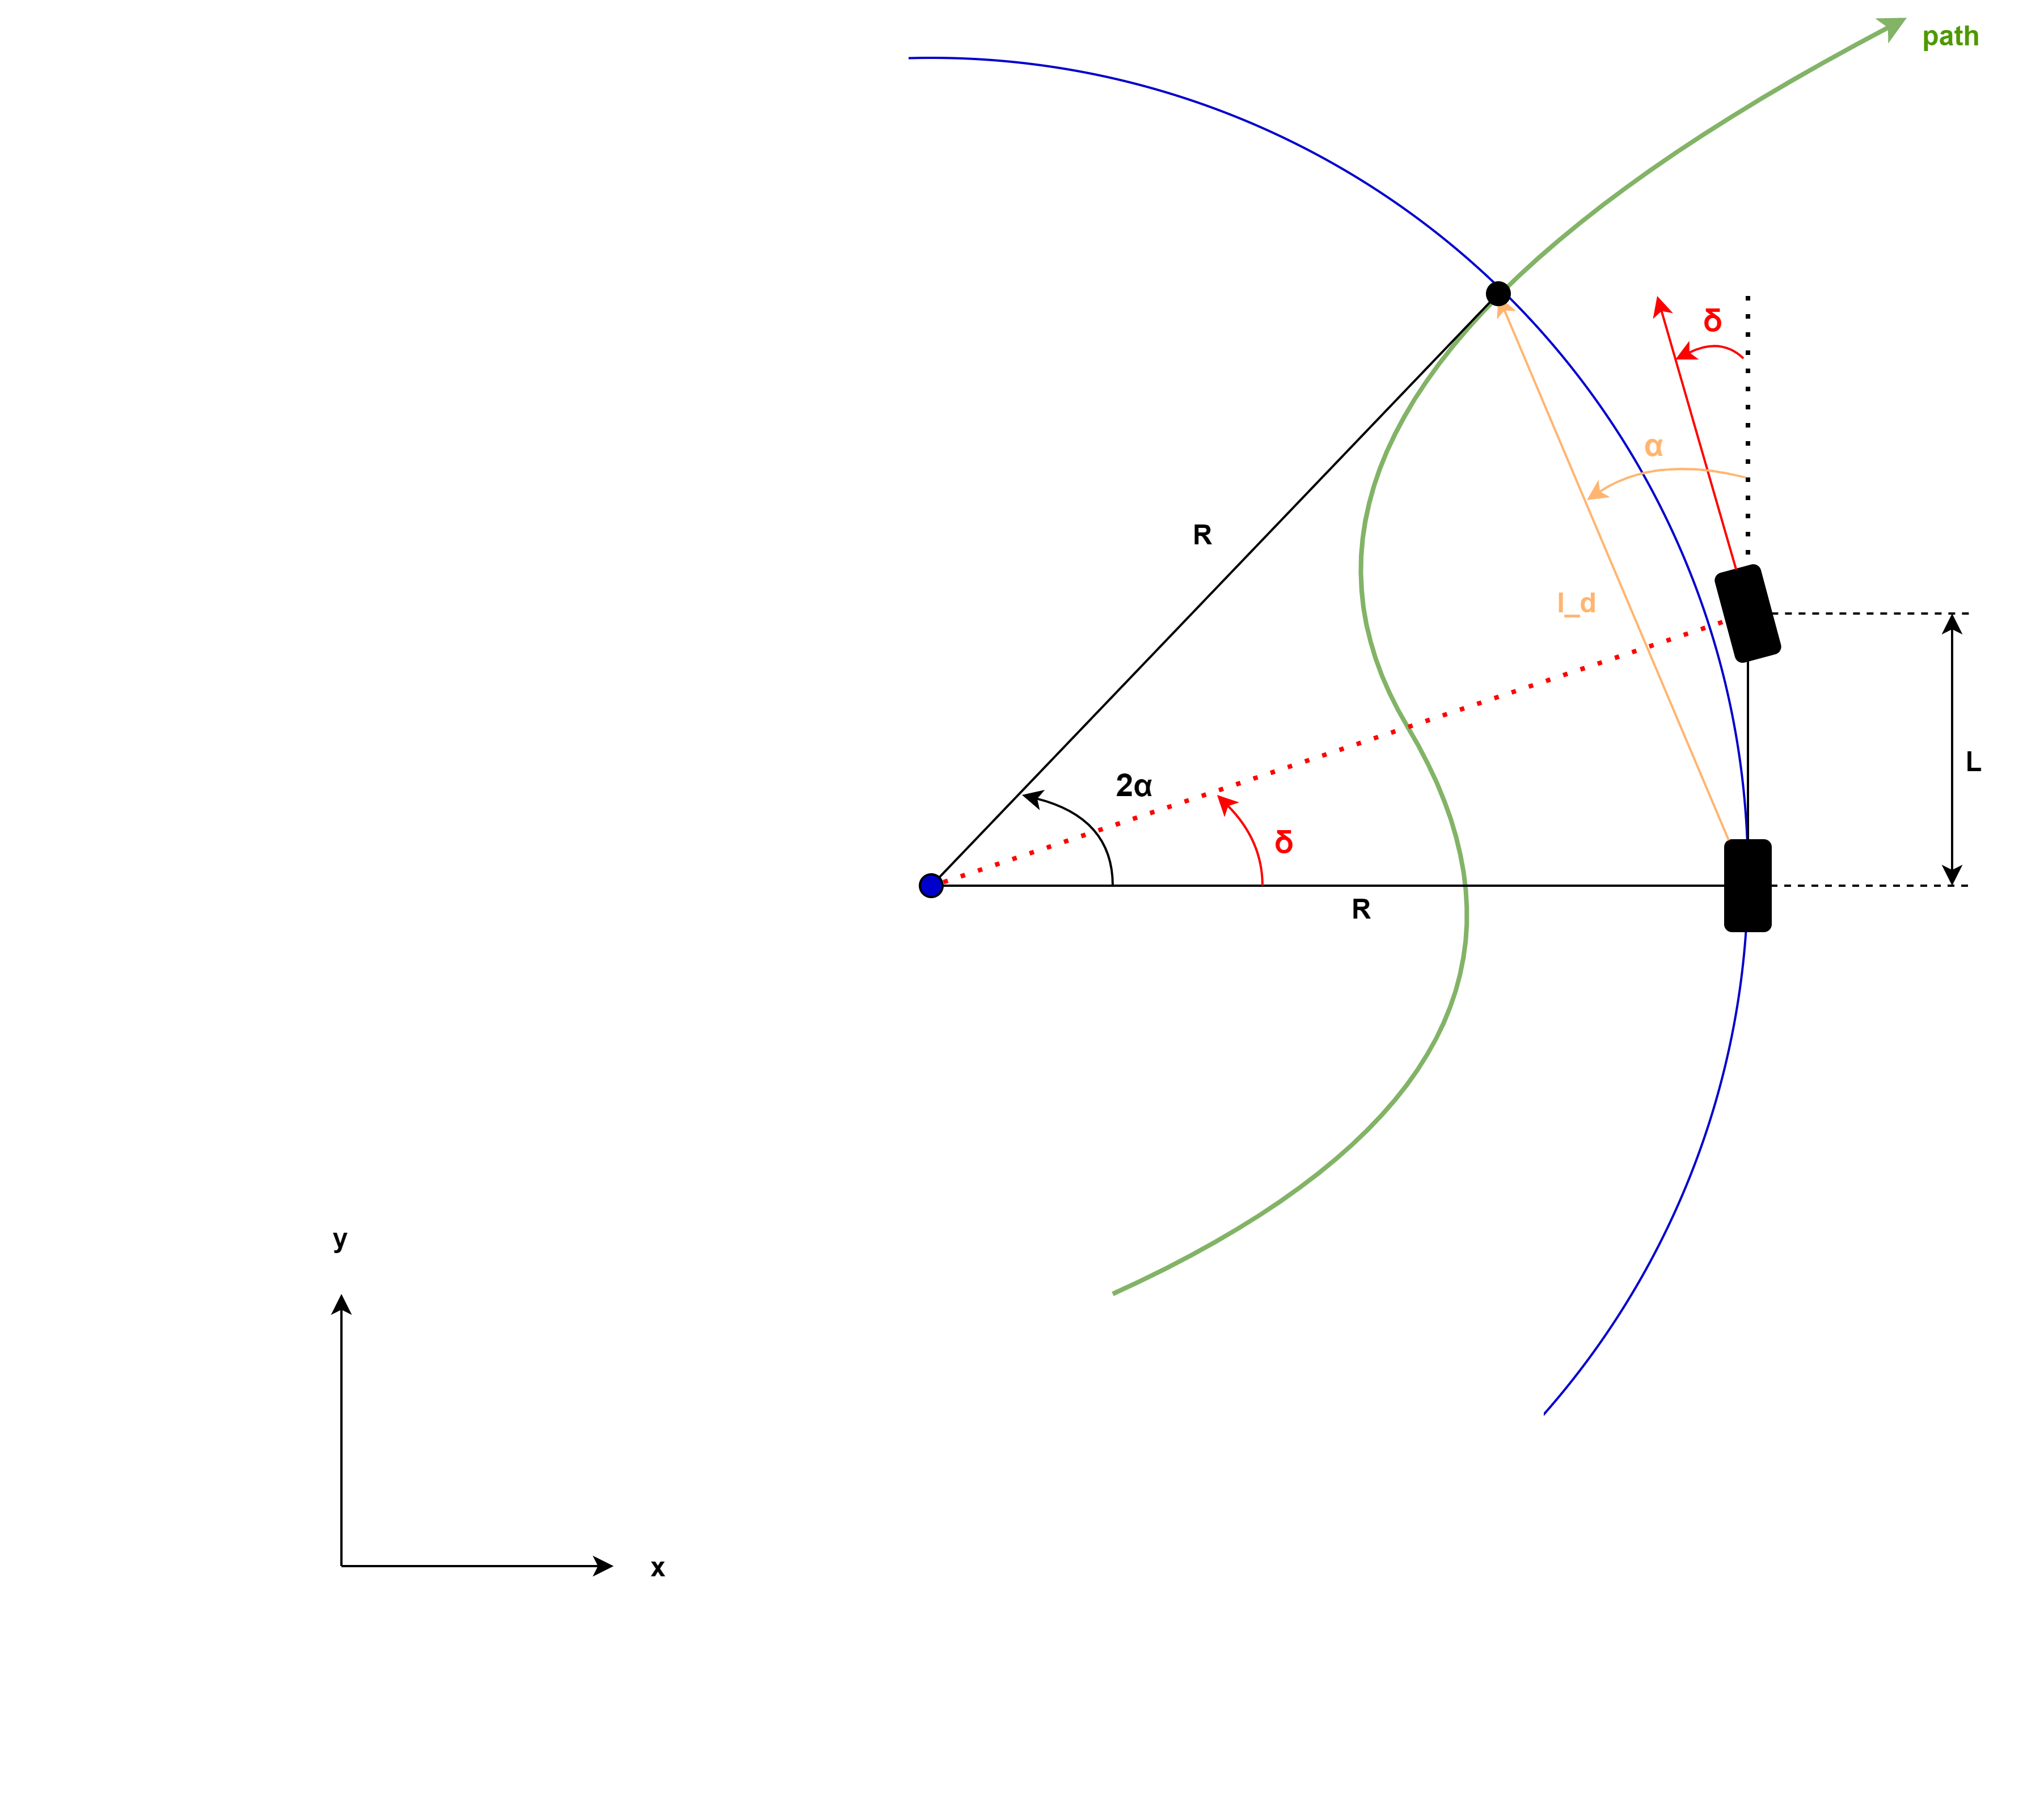

The steering angle $\delta$ can be calculated as follows:


$$\delta = arctan(\frac{L}{R})$$


From the law of sines, $R$ can be obtained:

 
$$\frac{l_d}{sin(2\alpha)} = \frac{R}{sin(\frac{\pi}{2} - \alpha)}$$



$$\frac{l_d}{2\sin(\alpha)\cos(\alpha)} = \frac{R}{cos(\alpha)}$$



$$R = \frac{l_d}{2\sin(\alpha)}$$


This results in:


$$\delta = arctan\left( \frac{2\ L\ sin(\alpha)}{l_{d}} \right)$$


### References

[https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html](https://www.mathworks.com/help/robotics/ug/pure-pursuit-controller.html)

[https://www.youtube.com/watch?v=qYR7mmcwT2w](https://www.youtube.com/watch?v=qYR7mmcwT2w)

Coulter, R. *Implementation of the Pure Pursuit Path Tracking Algorithm*. Carnegie Mellon University, Pittsburgh, Pennsylvania, Jan 1990.

## Pure Pursuit Waypoint Generator

To provide the reference waypoints for the Pure Pursuit algorithm, the [PurePursuitWPGenerator.m](matlab:open('./Vehicle Functions\PurePursuitWPGenerator.m')) is used:

First of all, the current posed is transformed to Frenet coordinates. Then, at every time step, the Frenet trajectory will be planned ([planFrenetTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('planFrenetTrajectory'));)). It will also be transformed to Cartesian coordinates for plotting. Finally the next waypoints in the trajectory ([getNextFrenetTrajectoryWaypoints](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('getNextFrenetTrajectoryWaypoints'));)) will be transformed back to Cartesian coordinates to provide the input for the Pure Pursuit algorithm.

## Lateral Stanley Controller

The Lateral Stanley Controller can also be used for path tracking. Using the kinematic bicycle model, the inputs are:

- The reference pose **[x_ref, y_ref, θ_ref]**: While only considering forward motion, the reference location x_ref, y_ref is the point on the path which is closest to the center of the vehicle's front axle. The reference angle θ_ref is the orientation at this reference location on the path in degrees.

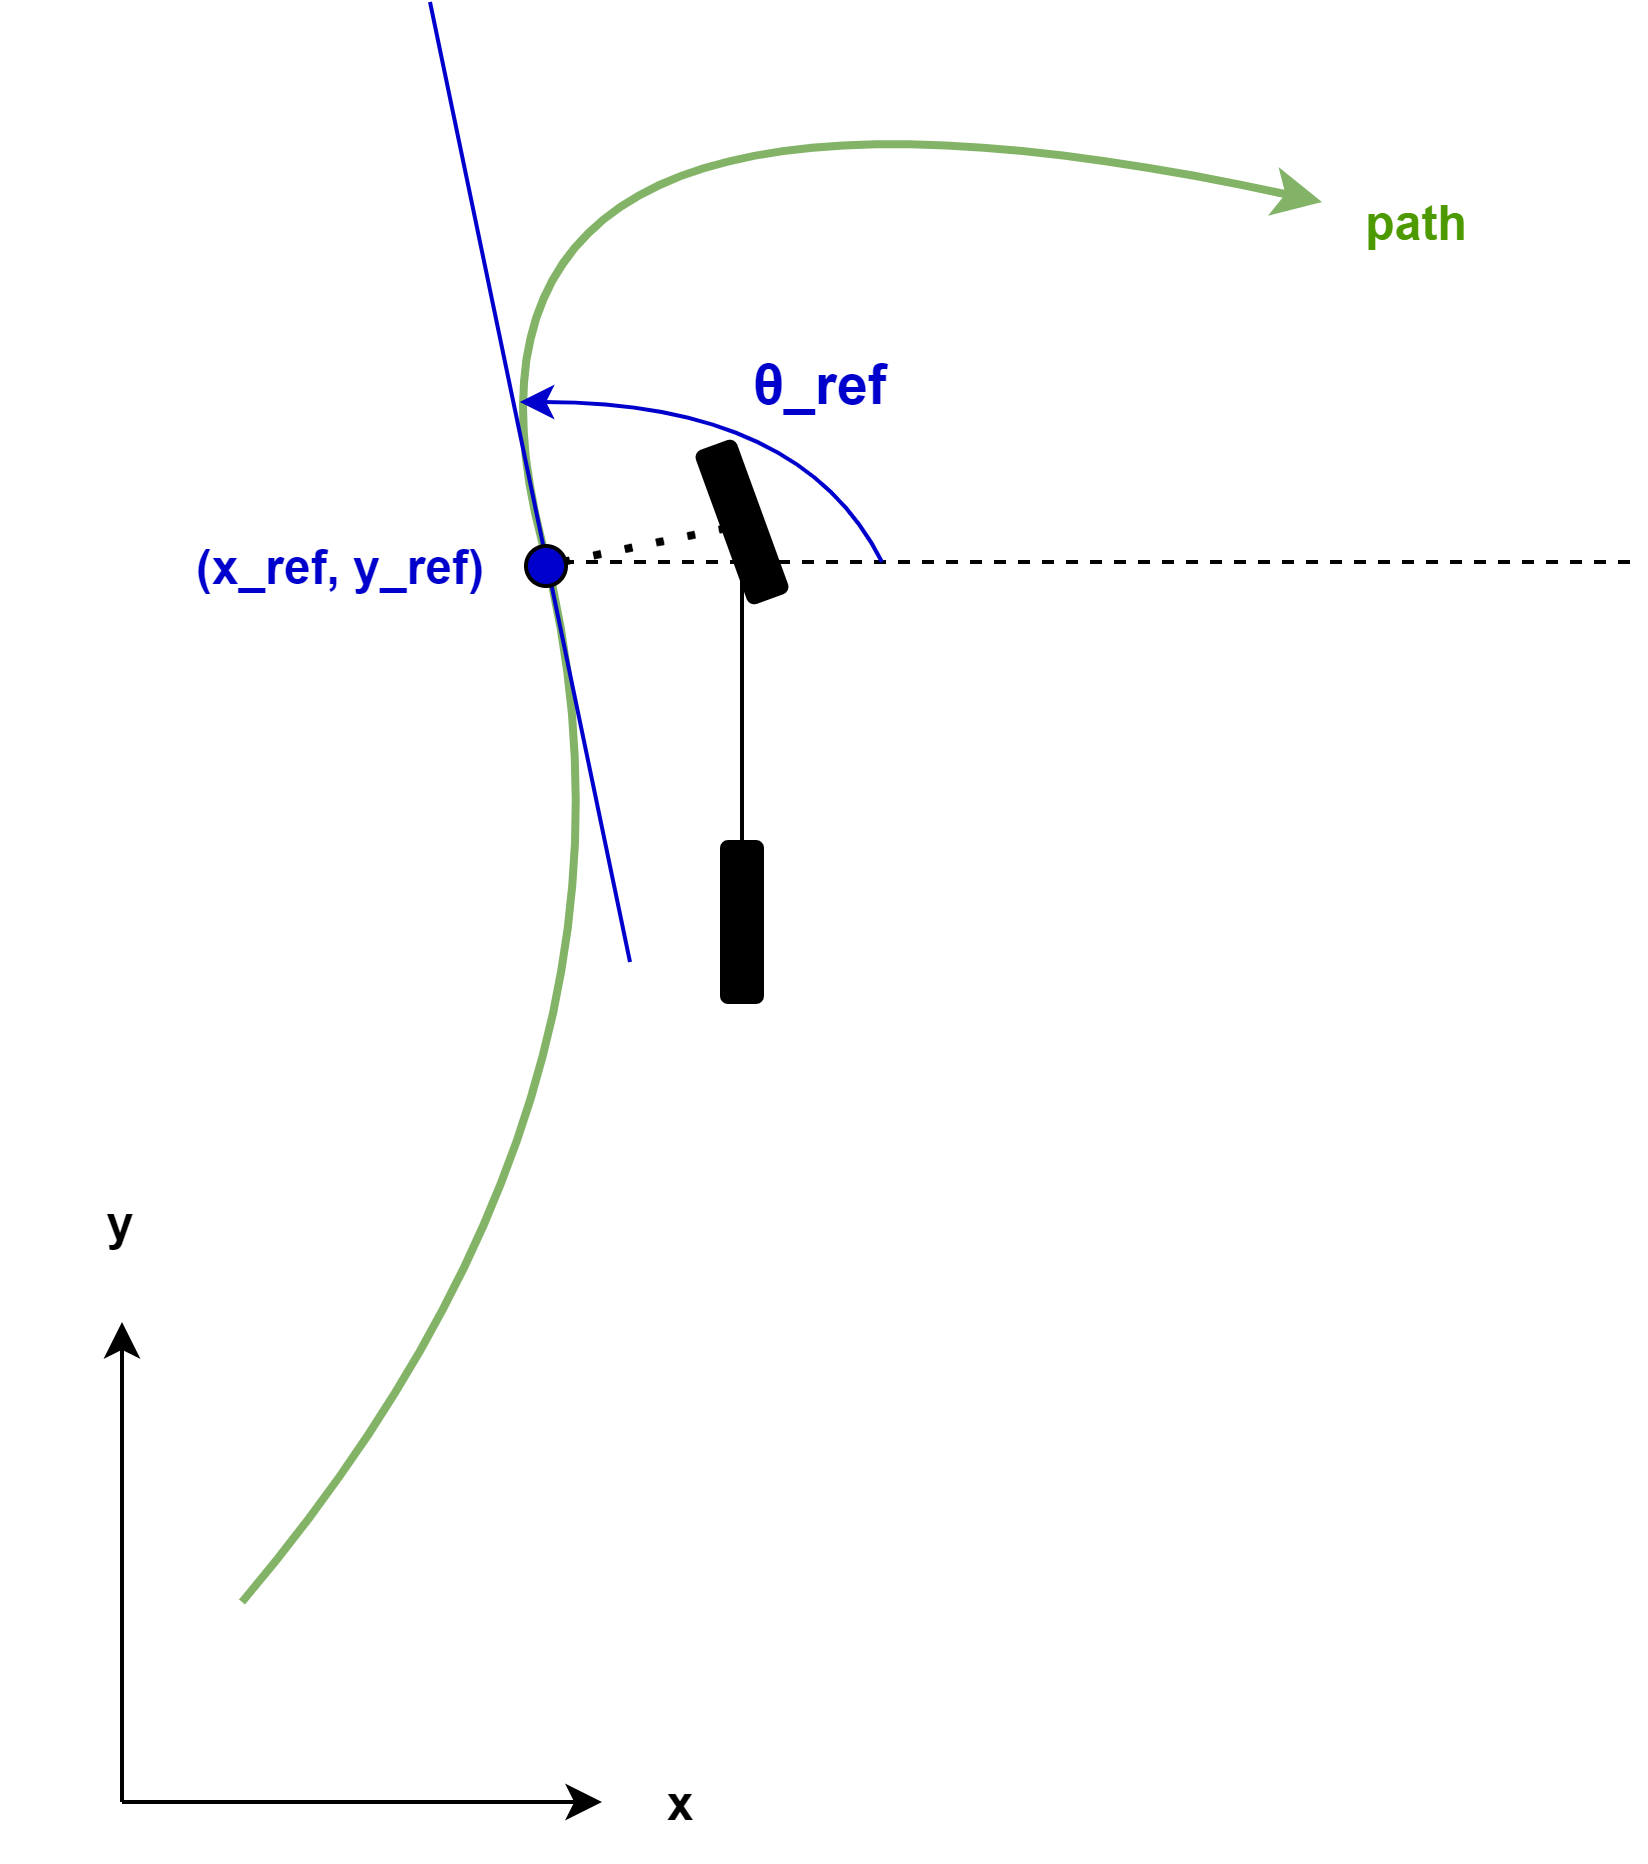

- The current pose **[x, y, θ]**: This is the current pose of the vehicle according to the center of the vehicle's rear axle. The current orientation θ must be in degrees.

- The current velocity of the vehicle in $\frac{m}{s}$

- The vehicle's direction: The constant 1 is used for forward motion.

The controller outputs the steering angle $\delta$ in degrees. Therefore, to use this angle as the input for the bicycle kinematic model, a transformation to radians is necessary.

### Position Gain Of Forward Motion

To tune the controller, the position gain can be adjusted. For forward motion, only the position gain for forward motion needs to be considered. The higher this value is, the more the position error will affect steering angle adjustmens.

### Steering Control Law

The steering control law considers the cross track error $e(t)$, the vehicles speed $v(t)$ and the vehicle's heading $\psi (t)$ with respect to the closest trajectory segment (see figure below). The reference point is the center of the vehicle's front axle. For the kinematic bicycle model, the steering angle $\delta(t)$ is calculated as follows, with $k$ being the gain and $\delta_{max}$ being the maximum steering angle:


$$\delta(t) =
    \begin{cases}
      \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) & \text{if } |\psi(t) + arctan(\frac{k\ e(t)}{v(t)})| < \delta_{max} \\
      \delta_{max} & \text{if }  \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \geq \delta_{max} \\
      -\delta_{max}  &  \text{if } \psi(t) + arctan(\frac{k\ e(t)}{v(t)}) \leq \delta_{max} \\
    \end{cases} $$


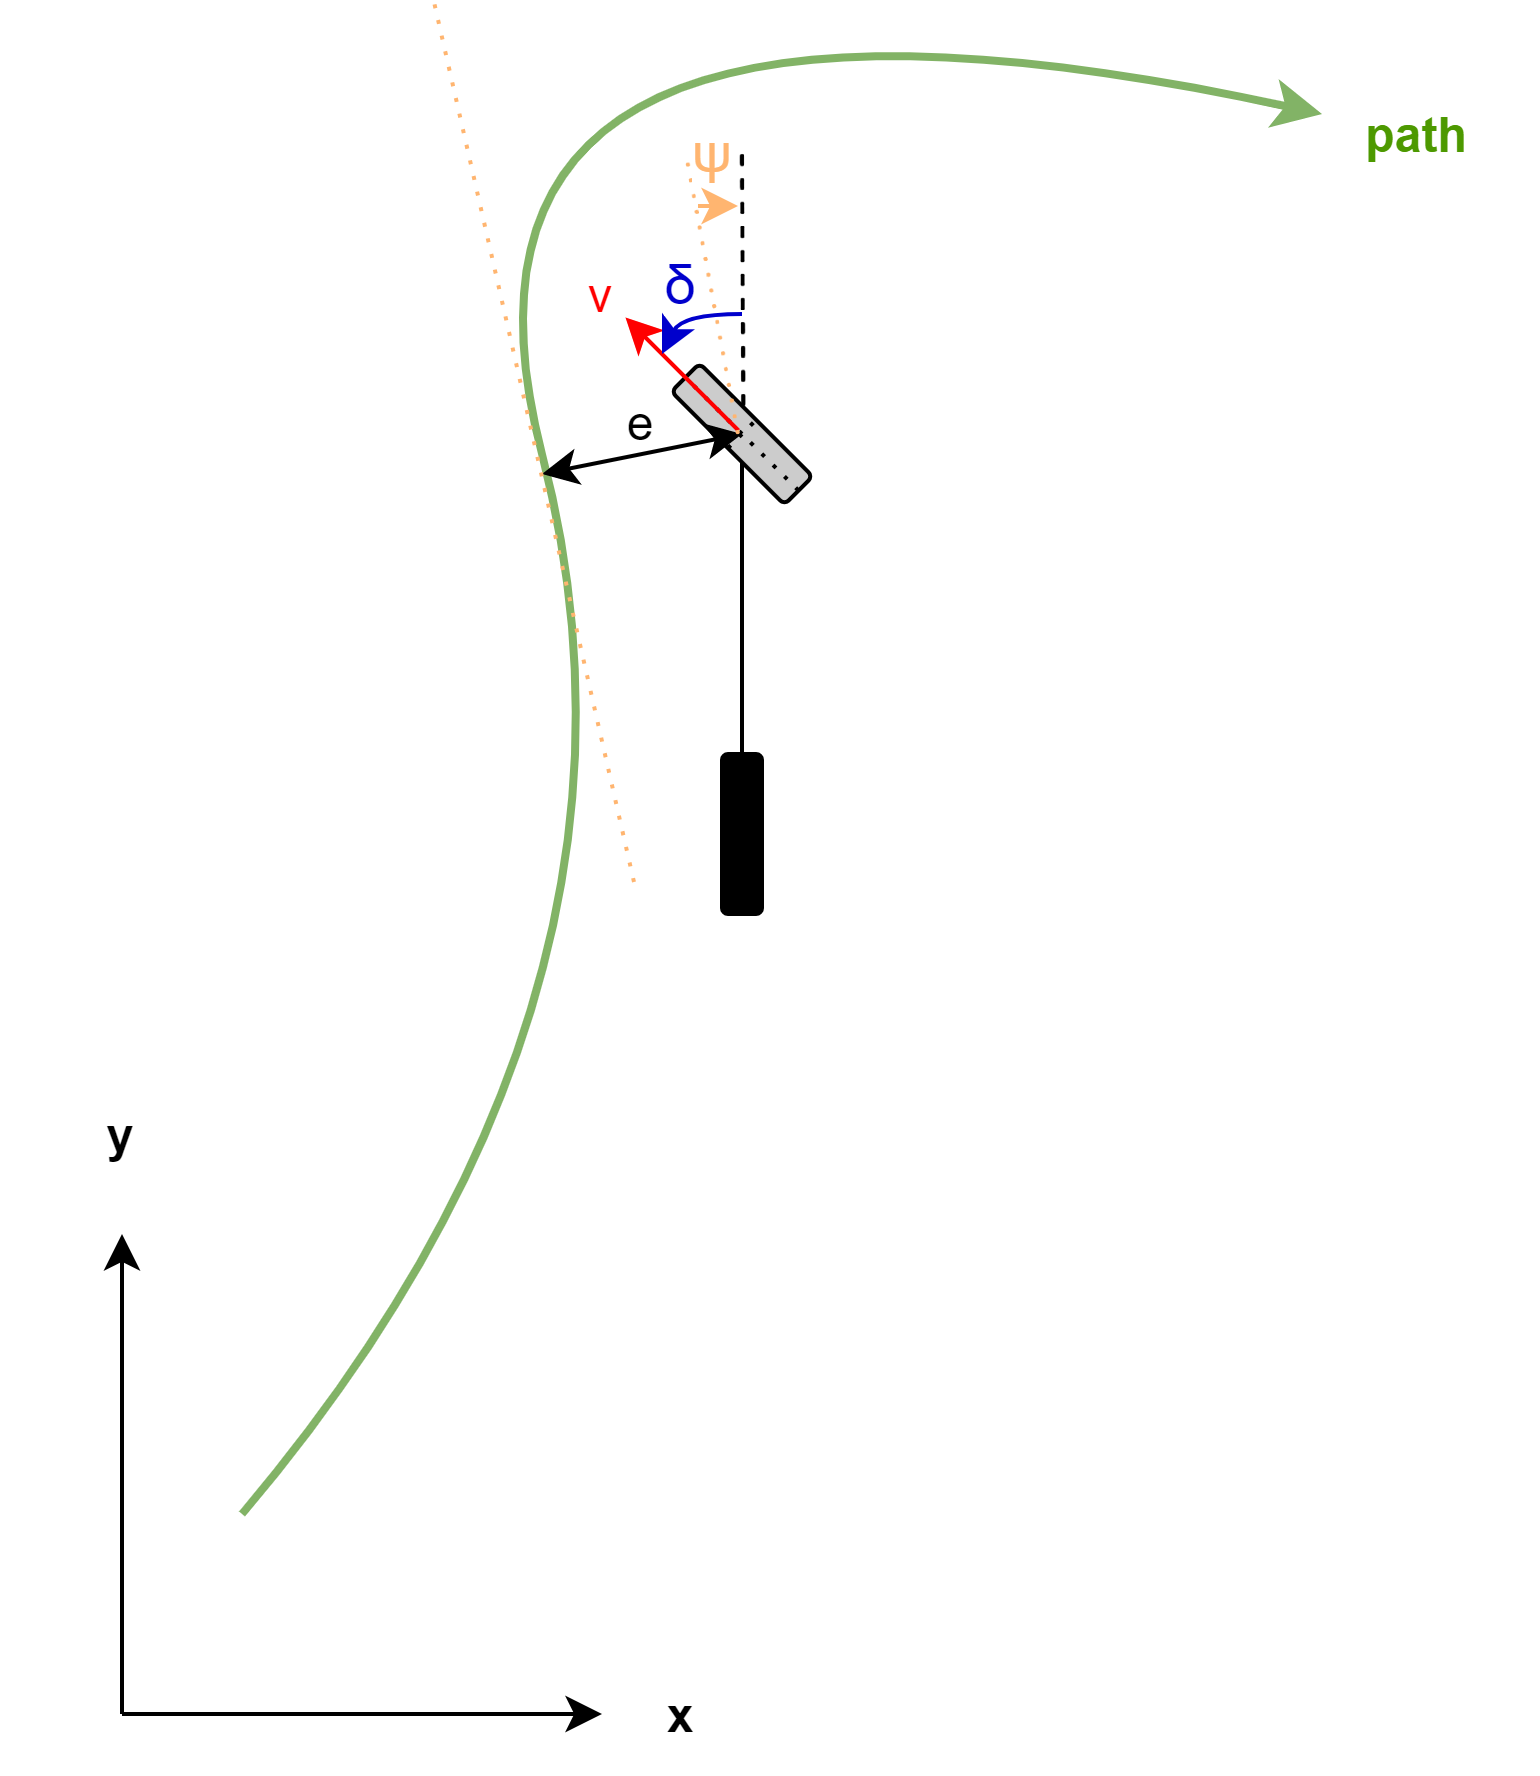

### Error Minimisation

To reduce the cross lateral error $\Delta d = d_{actual} - d_{reference}}$ for tracking the desired path, the [Global Optimization Toolbox](https://www.mathworks.com/products/global-optimization.html) with a [Genetic Algorithm](https://www.mathworks.com/discovery/genetic-algorithm.html) is used. Therefore the functions [error_d_optimisation](matlab:open('./Vehicle Functions\Helper Functions\error_d_optimisation.m')) and [error_d](matlab:open('./Vehicle Functions\Helper Functions\error_d.m')) are created, to find the optimal value for the position gain of forward motion.

### References

[https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html](https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html)

[https://www.youtube.com/watch?v=9Y7kVIJs_JI](https://www.youtube.com/watch?v=9Y7kVIJs_JI)

Hoffmann, Gabriel M., Claire J. Tomlin, Michael Montemerlo, and Sebastian Thrun. "Autonomous Automobile Trajectory Tracking for Off-Road Driving: Controller Design, Experimental Validation and Racing." *American Control Conference*. 2007, pp. 2296–2301. doi:10.1109/ACC.2007.4282788

## Stanley Pose Generator

To provide the reference pose for the Stanley controller, the [StanleyPoseGenerator.m](matlab:open('./Vehicle Functions\StanleyPoseGenerator.m')) is used:

First of all, the current posed is transformed to Frenet coordinates. Then, at every time step, the Frenet trajectory will be planned ([planFrenetTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('LocalTrajectoryPlanner.m'),  getFunctionLineNr('planFrenetTrajectory'));)). It will also be transformed to Cartesian coordinates for the reference pose and for plotting. A reference pose according to the center of the ego vehicle's front axle([getVehicleFrontAxleCenterPoint](matlab:open('./Vehicle Functions\Helper Functions\getVehicleFrontAxleCenterPoint.m'))) must be generated ([getReferencePoseStanley](matlab:matlab.desktop.editor.openAndGoToLine(which('StanleyPoseGenerator.m'),  getFunctionLineNr('getReferencePoseStanley'));)):

It is necessary to find the waypoint on the trajectory which is closest to the center of the vehicle's front axle ([getClosestPointOnTrajectory](matlab:matlab.desktop.editor.openAndGoToLine(which('StanleyPoseGenerator.m'),  getFunctionLineNr('getClosestPointOnTrajectory'));)). This will return the reference position in Cartesian coordinates. To get the reference orientation, the slope of the waypoint before and after the found reference waypoint is calculated.

# Vizualisation

# Helper Functions